%% 
% Assignment Three
% Manouchehr Mohammadi

%% Define symbolic variables
%%
clear
close all
clc
syms m k c real
assumeAlso(m > 0);
assumeAlso(k > 0);
assumeAlso(c > 0);
syms zeta
%% We can have some exact numbers for the spring constant and the mass.
k=100;
m=1;
oms = sqrt(k/m);
%zeta=0;
c=2*m*oms*zeta;
disp(c);

$$20\,\zeta$$

%% External Force
syms F0 w
F0=1;
%% Making the Equation
syms t A B
xs(t)=A*sin(w*t)+B*cos(w*t);
disp(xs);

$$B\,\cos\left(t\,w\right)+A\,\sin\left(t\,w\right)$$

F(t)=F0*cos(w*t);
disp(F)

$$\cos\left(t\,w\right)$$

xp = diff(xs, t);
xpp = diff(xp, t);
eq=m*xpp+c*xp+k*xs-F(t);
disp(eq)

$$100\,B\,\cos\left(t\,w\right)-\cos\left(t\,w\right)+100\,A\,\sin\left(t\,w\right)+20\,\zeta \,\left(A\,w\,\cos\left(t\,w\right)-B\,w\,\sin\left(t\,w\right)\right)-B\,w^{2}\,\cos\left(t\,w\right)-A\,w^{2}\,\sin\left(t\,w\right)$$

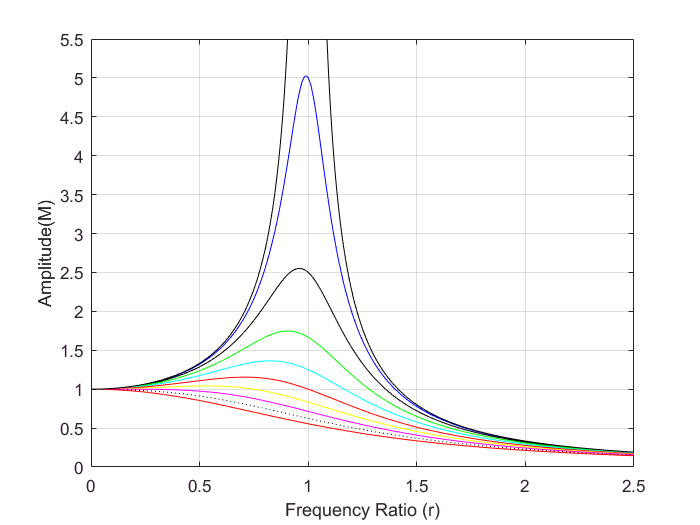


%%

A=(F0*c*w)/((k-m*w^2)^2+(c*w)^2);
B=F0*(k-m*w^2)/((k-m*w^2)^2+(c*w)^2);
w=0:0.01:25;
a=(k-m*w.^2).^2;
b=(c*w).^2;
X=(F0)./(sqrt(a+b));
%%
X0=F0/k;
r=w/oms;
%%
M=X/X0;
for i=0.1:0.1:1
M1=subs(M,zeta,0.1);
M2=subs(M,zeta,0.2);
M3=subs(M,zeta,0.3);
M4=subs(M,zeta,0.4);
M5=subs(M,zeta,0.5);
M6=subs(M,zeta,0.6);
M7=subs(M,zeta,0.7);
M8=subs(M,zeta,0.8);
M9=subs(M,zeta,0.9);
M10=subs(M,zeta,1e-2);
end
plot(r,M1,'b',r,M2,'k',r,M3,'g',r,M4,'c',r,M5,'r',r,M6,'y',r,M7,'m',r,M8,':k',r,M9,'-r',r,M10,'-k')
axis([0 2.5 0 5.5])
grid on
xlabel('Frequency Ratio (r)')
ylabel('Amplitude(M)')